% =========================================================================
% problem4_2.m  (重写版本，2026-05)
% 问题四(2)：离网模式 + 储能配置 + 24 场景最优调度
% -------------------------------------------------------------------------
% 修改点（相对旧版）：
%   1) 离网运行：删除 buy/sell，新增 curt（弃风弃光），无外购电、无上网电
%   2) E_init = |min(b)| × P_h2 / η（A 方案，与 E_cap 同口径）
%   3) 功率平衡：P_h2*t + ch - η*dis + curt = 风光发电 - 常规负荷
%   4) 储能动态：直接用能量 E (MW·h)，不再用 SOC 标幺
%   5) 充放电互斥：0-1 变量 z + Big-M，使用 intlinprog
%   6) 5 个低出力场景物理不可行，捕获并标记
% =========================================================================
% 依赖：上层 workspace 已加载 wind1..wind6, sun1..sun4, classicload
% =========================================================================

wind_vectors = {wind1(:), wind2(:), wind3(:), wind4(:), wind5(:), wind6(:)};
wind_names   = {'wind1', 'wind2', 'wind3', 'wind4', 'wind5', 'wind6'};
sun_vectors  = {sun1(:), sun2(:), sun3(:), sun4(:)};
sun_names    = {'sun1', 'sun2', 'sun3', 'sun4'};

classicload  = classicload(:);
n      = numel(wind_vectors{1});
lb_t   = 0.1;
P_h2   = 20.75 * 2;             % 制氢氨满载等效功率 (MW)，扩容 2 倍
eta    = 0.998 * 0.9 * 0.9;     % 放电链路效率 = 自损耗0.998 × 充电0.9 × 放电0.9
P_w    = 40;                    % 风电装机 (MW)
P_s    = 64;                    % 光伏装机 (MW)
P_L    = 6;                     % 常规负荷峰值 (MW)
M_big  = 200.0;                 % Big-M 上界 (MW)，远大于任何单时段功率

% =========================================================================
% 第一步：计算各场景弃电/缺电向量，确定最大弃电场景
% =========================================================================
fprintf('==================== 第一步：弃电/缺电向量分析 ====================\n');

==================== 第一步：弃电/缺电向量分析 ====================



slack_vectors  = cell(numel(wind_vectors), numel(sun_vectors));
best_max_slack = -Inf;
best_wind_idx  = 1;
best_sun_idx   = 1;

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};

        raw_ub = (wind*P_w + sun*P_s - classicload*P_L) / P_h2;
        ub_val = min(ones(n,1), raw_ub);

        slack = zeros(n,1);
        for i = 1:n
            if ub_val(i) < lb_t
                slack(i) = ub_val(i) - lb_t;   % 缺电：负值
            elseif raw_ub(i) > 1
                slack(i) = raw_ub(i) - 1;       % 弃电：正值
            end
        end

        slack_vectors{wind_idx, sun_idx} = slack;

        if max(slack) > best_max_slack
            best_max_slack = max(slack);
            best_wind_idx  = wind_idx;
            best_sun_idx   = sun_idx;
        end
    end
end

fprintf('最大弃电场景：%s + %s（最大弃电量 = %.4g）\n', ...
        wind_names{best_wind_idx}, sun_names{best_sun_idx}, best_max_slack);

最大弃电场景：wind1 + sun1（最大弃电量 = 0.6422）



% =========================================================================
% 第二步：由最大弃电场景计算储能容量 E_cap 与初始储能 E_init
% =========================================================================
best_slack = slack_vectors{best_wind_idx, best_sun_idx};
b = cumsum(best_slack);

[max_b, max_b_idx] = max(b);
min_b_after = min(b(max_b_idx:end));   % max(b) 之后的最小值
min_b_global = min(b);                  % 全程最低点（用于 E_init）

E_cap  = (max_b - min_b_after) * P_h2 / eta;
% A 方案：E_init 与 E_cap 同口径，除以 η
E_init = max(0, -min_b_global) * P_h2 / eta;

fprintf('b 向量：max = %.4g（位置 %d），max 之后最小 = %.4g，全程最小 = %.4g\n', ...
        max_b, max_b_idx, min_b_after, min_b_global);

b 向量：max = 3.261（位置 16），max 之后最小 = 3.064，全程最小 = 0


fprintf('储能容量 E_cap  = %.4f MW·h\n', E_cap);

储能容量 E_cap  = 10.0797 MW·h


fprintf('初始储能 E_init = %.4f MW·h\n', E_init);

初始储能 E_init = 0.0000 MW·h


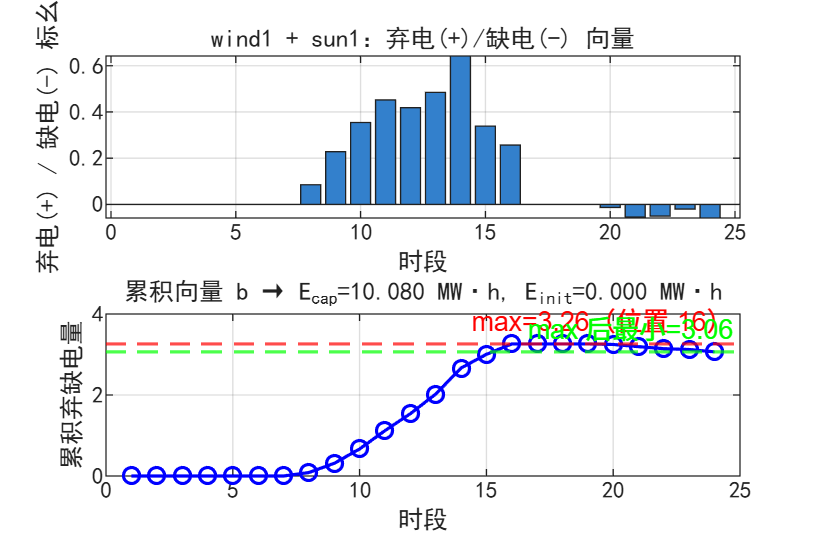


% ----------------------- 第二步绘图 -----------------------
figure('Name', 'problem4-2：最大弃电场景储能容量计算', 'Color', 'w', ...
       'Position', [100 100 900 600]);
subplot(2,1,1);
bar(best_slack, 'FaceColor', [0.2 0.5 0.8]); grid on;
title(sprintf('%s + %s：弃电(+)/缺电(-) 向量', ...
      wind_names{best_wind_idx}, sun_names{best_sun_idx}), 'Interpreter', 'none');
xlabel('时段'); ylabel('弃电(+) / 缺电(-) 标幺');

subplot(2,1,2);
plot(b, 'b-o', 'LineWidth', 1.2); grid on; hold on;
yline(max_b,       'r--', sprintf('max=%.3g（位置 %d）', max_b, max_b_idx), 'LineWidth', 1.2);
yline(min_b_after, 'g--', sprintf('max 后最小=%.3g', min_b_after), 'LineWidth', 1.2);
if min_b_global < 0
    yline(min_b_global, 'm--', sprintf('全程最小=%.3g', min_b_global), 'LineWidth', 1.2);
end
title(sprintf('累积向量 b → E_{cap}=%.3f MW·h, E_{init}=%.3f MW·h', E_cap, E_init), ...
      'Interpreter', 'tex');
xlabel('时段'); ylabel('累积弃缺电量');


% =========================================================================
% 第三步：24 场景 MILP 调度（intlinprog）
% =========================================================================
fprintf('\n==================== 第三步：24 场景 MILP 调度 ====================\n');


==================== 第三步：24 场景 MILP 调度 ====================


fprintf('储能容量 E_cap = %.4f MW·h，初始储能 E_init = %.4f MW·h\n\n', E_cap, E_init);

储能容量 E_cap = 10.0797 MW·h，初始储能 E_init = 0.0000 MW·h




opts_milp = optimoptions('intlinprog', 'Display', 'off', ...
                         'RelativeGapTolerance', 1e-6);

storage_results = struct([]);
res_idx = 0;
failed_cases = {};

for wind_idx = 1:numel(wind_vectors)
    wind = wind_vectors{wind_idx};
    wind_name = wind_names{wind_idx};

    for sun_idx = 1:numel(sun_vectors)
        sun = sun_vectors{sun_idx};
        sun_name = sun_names{sun_idx};

        fprintf('---- 场景 %02d：%s + %s ----\n', ...
                (wind_idx-1)*numel(sun_vectors)+sun_idx, wind_name, sun_name);

        % -------------- 决策变量布局 --------------
        % x = [t(n); E(n); ch(n); dis(n); z(n); curt(n)]，总长 6n
        % t   ：制氢氨标幺出力                   ∈ [0.1, 1]
        % E   ：第 i 时段末电池储能 (MW·h)       ∈ [0, E_cap]
        % ch  ：充电功率 (MW)                    ≥ 0
        % dis ：放电功率（电池内部释放量, MW）   ≥ 0
        % z   ：充放电标志（1=充电，0=放电）     ∈ {0,1}
        % curt：弃风弃光功率 (MW)                ≥ 0
        idx_t   = @(i) i;
        idx_E   = @(i) n + i;
        idx_ch  = @(i) 2*n + i;
        idx_dis = @(i) 3*n + i;
        idx_z   = @(i) 4*n + i;
        idx_cu  = @(i) 5*n + i;
        N = 6 * n;

        % -------------- 目标：min -sum(t) --------------
        f_milp = zeros(N, 1);
        for i = 1:n, f_milp(idx_t(i)) = -1; end

        % -------------- 变量界 --------------
        lb_milp = zeros(N, 1);
        ub_milp = inf(N, 1);
        for i = 1:n
            lb_milp(idx_t(i))   = lb_t;   ub_milp(idx_t(i))   = 1;
            lb_milp(idx_E(i))   = 0;      ub_milp(idx_E(i))   = E_cap;
            lb_milp(idx_ch(i))  = 0;      ub_milp(idx_ch(i))  = M_big;
            lb_milp(idx_dis(i)) = 0;      ub_milp(idx_dis(i)) = M_big;
            lb_milp(idx_z(i))   = 0;      ub_milp(idx_z(i))   = 1;
            lb_milp(idx_cu(i))  = 0;      ub_milp(idx_cu(i))  = M_big;
        end

        % -------------- 整数变量索引（z） --------------
        intcon = arrayfun(@(i) idx_z(i), 1:n);

        % -------------- 等式约束 1：功率平衡 --------------
        % P_h2*t + ch - η*dis + curt = wind*P_w + sun*P_s - load*P_L
        Aeq1 = zeros(n, N);
        beq1 = wind*P_w + sun*P_s - classicload*P_L;
        for i = 1:n
            Aeq1(i, idx_t(i))   = P_h2;
            Aeq1(i, idx_ch(i))  = 1;
            Aeq1(i, idx_dis(i)) = -eta;
            Aeq1(i, idx_cu(i))  = 1;
        end

        % -------------- 等式约束 2：储能动态 --------------
        % E_i - E_{i-1} - ch_i + dis_i = 0,  E_0 = E_init
        % 损耗已在功率平衡侧 (η·dis) 体现，电池内部按净进出量
        Aeq2 = zeros(n, N);
        beq2 = zeros(n, 1);
        for i = 1:n
            Aeq2(i, idx_E(i))   = 1;
            if i > 1
                Aeq2(i, idx_E(i-1)) = -1;
            else
                beq2(i) = E_init;       % E_1 - E_init = ch_1 - dis_1 → 移项到右边
            end
            Aeq2(i, idx_ch(i))  = -1;
            Aeq2(i, idx_dis(i)) = 1;
        end

        Aeq = [Aeq1; Aeq2];
        beq = [beq1; beq2];

        % -------------- 不等式约束：充放电互斥 (Big-M) --------------
        % ch_i  ≤ M*z_i        ↔  ch_i  - M*z_i  ≤ 0
        % dis_i ≤ M*(1-z_i)    ↔  dis_i + M*z_i  ≤ M
        A_ineq = zeros(2*n, N);
        b_ineq = zeros(2*n, 1);
        for i = 1:n
            A_ineq(i,     idx_ch(i))  = 1;
            A_ineq(i,     idx_z(i))   = -M_big;
            b_ineq(i)                  = 0;

            A_ineq(n+i,   idx_dis(i)) = 1;
            A_ineq(n+i,   idx_z(i))   = M_big;
            b_ineq(n+i)                = M_big;
        end

        % -------------- 求解 --------------
        [x_sol, fval, exitflag] = intlinprog(f_milp, intcon, A_ineq, b_ineq, ...
                                              Aeq, beq, lb_milp, ub_milp, opts_milp);

        if exitflag ~= 1 || isempty(x_sol)
            fprintf('  ✗ MILP 不可行 (exitflag=%d)：储能容量不足以支撑该低出力场景\n', exitflag);
            failed_cases{end+1} = sprintf('%s+%s', wind_name, sun_name); %#ok<SAGROW>
            continue;
        end

        % -------------- 提取解 --------------
        t_opt    = x_sol(1:n);
        E_opt    = x_sol(n+1:2*n);
        ch_opt   = x_sol(2*n+1:3*n);
        dis_opt  = x_sol(3*n+1:4*n);
        z_opt    = x_sol(4*n+1:5*n);
        curt_opt = x_sol(5*n+1:6*n);

        % -------------- 校验 --------------
        lhs = P_h2*t_opt + ch_opt - eta*dis_opt + curt_opt;
        rhs = wind*P_w + sun*P_s - classicload*P_L;
        err_balance = max(abs(lhs - rhs));
        overlap_n = sum((ch_opt > 1e-3) & (dis_opt > 1e-3));
        if err_balance > 1e-4
            warning('功率平衡误差较大: %.2e', err_balance);
        end
        if overlap_n > 0
            warning('同时充放电时段数 = %d (应为 0)', overlap_n);
        end

        % -------------- 指标计算 --------------
        sum_t           = sum(t_opt);
        gen_total       = sum(wind*P_w + sun*P_s);
        nh3load_vec     = t_opt * P_h2;
        annual_nh3      = sum_t * 3 * 365;          % 全年制氨量 (吨)
        cap_utilization = sum_t / n;                % 时间维度产能利用率
        power_util      = sum_t * P_h2 / gen_total; % 发电利用率
        curt_total      = sum(curt_opt);
        curt_rate       = curt_total / gen_total;   % 弃风弃光率
        ch_total        = sum(ch_opt);
        dis_total_net   = sum(dis_opt) * eta;       % 实际进网放电量
        cycle_depth     = (max(E_opt) - min(E_opt)) / E_cap;
        mean_E          = mean(E_opt);

        % -------------- 成本（沿用 problem4_1 口径，去掉买卖电） --------------
        % 项目：电解槽运维 + 合成氨投资摊销 + 风电度电成本 + 光伏度电成本
        cost_om     = 0.75*2*sum_t*2 + 10*2*sum_t*100 + 10*2*sum_t*150;  % 制氢氨运维
        cost_nh3_cap= 1.5*2*1000*0.2*60000/365/30;                       % 合成氨投资日摊
        cost_pv     = sum(sun)*P_s*1000*0.12;
        cost_wind   = sum(wind)*P_w*1000*0.15;
        % 储能投资日摊（电储能 1000 元/kWh，寿命 15 年）
        cost_storage = E_cap * 1000 * 1000 / 365 / 15;                   % 元/天
        cost_total  = cost_om + cost_nh3_cap + cost_pv + cost_wind + cost_storage;
        J_storage   = cost_total / (sum_t * 3);                          % 元/吨氨

        fprintf('  ✓ sum(t)=%.4f, 制氨/年=%.1f t, 产能利用率=%.2f%%, 发电利用率=%.2f%%, 弃电率=%.2f%%\n', ...
                sum_t, annual_nh3, cap_utilization*100, power_util*100, curt_rate*100);
        fprintf('    E∈[%.2f, %.2f] MW·h（循环深度=%.1f%%）, 吨氨成本=%.1f 元\n', ...
                min(E_opt), max(E_opt), cycle_depth*100, J_storage);

        % -------------- 写入结果 --------------
        res_idx = res_idx + 1;
        storage_results(res_idx).case_idx        = res_idx;
        storage_results(res_idx).wind_idx        = wind_idx;
        storage_results(res_idx).wind_name       = wind_name;
        storage_results(res_idx).sun_idx         = sun_idx;
        storage_results(res_idx).sun_name        = sun_name;
        storage_results(res_idx).t_opt           = t_opt;
        storage_results(res_idx).E_opt           = E_opt;
        storage_results(res_idx).ch_opt          = ch_opt;
        storage_results(res_idx).dis_opt         = dis_opt;
        storage_results(res_idx).curt_opt        = curt_opt;
        storage_results(res_idx).sum_t           = sum_t;
        storage_results(res_idx).annual_nh3      = annual_nh3;
        storage_results(res_idx).cap_utilization = cap_utilization;
        storage_results(res_idx).power_util      = power_util;
        storage_results(res_idx).curt_total      = curt_total;
        storage_results(res_idx).curt_rate       = curt_rate;
        storage_results(res_idx).cycle_depth     = cycle_depth;
        storage_results(res_idx).mean_E          = mean_E;
        storage_results(res_idx).max_ch          = max(ch_opt);
        storage_results(res_idx).max_dis         = max(dis_opt);
        storage_results(res_idx).J               = J_storage;
        storage_results(res_idx).err_balance     = err_balance;
    end
end

---- 场景 01：wind1 + sun1 ----


  ✓ sum(t)=13.8281, 制氨/年=15141.8 t, 产能利用率=57.62%, 发电利用率=75.33%, 弃电率=16.44%


    E∈[0.00, 10.08] MW·h（循环深度=100.0%）, 吨氨成本=4177.3 元


---- 场景 02：wind1 + sun2 ----


  ✓ sum(t)=10.6157, 制氨/年=11624.2 t, 产能利用率=44.23%, 发电利用率=87.55%, 弃电率=0.00%


    E∈[0.00, 10.08] MW·h（循环深度=100.0%）, 吨氨成本=3962.5 元


---- 场景 03：wind1 + sun3 ----


  ✓ sum(t)=6.6215, 制氨/年=7250.6 t, 产能利用率=27.59%, 发电利用率=81.43%, 弃电率=0.00%


    E∈[0.00, 10.08] MW·h（循环深度=100.0%）, 吨氨成本=4345.4 元


---- 场景 04：wind1 + sun4 ----


  ✗ MILP 不可行 (exitflag=-2)：储能容量不足以支撑该低出力场景


---- 场景 05：wind2 + sun1 ----


  ✗ MILP 不可行 (exitflag=-2)：储能容量不足以支撑该低出力场景


---- 场景 06：wind2 + sun2 ----


  ✗ MILP 不可行 (exitflag=-2)：储能容量不足以支撑该低出力场景


---- 场景 07：wind2 + sun3 ----


  ✗ MILP 不可行 (exitflag=-2)：储能容量不足以支撑该低出力场景


---- 场景 08：wind2 + sun4 ----


  ✗ MILP 不可行 (exitflag=-2)：储能容量不足以支撑该低出力场景


---- 场景 09：wind3 + sun1 ----


  ✓ sum(t)=14.5036, 制氨/年=15881.5 t, 产能利用率=60.43%, 发电利用率=77.08%, 弃电率=14.89%


    E∈[0.00, 10.08] MW·h（循环深度=100.0%）, 吨氨成本=4126.2 元


---- 场景 10：wind3 + sun2 ----


  ✓ sum(t)=11.1047, 制氨/年=12159.7 t, 产能利用率=46.27%, 发电利用率=88.24%, 弃电率=0.00%


    E∈[0.00, 3.73] MW·h（循环深度=37.0%）, 吨氨成本=3947.3 元


---- 场景 11：wind3 + sun3 ----


  ✓ sum(t)=7.1277, 制氨/年=7804.8 t, 产能利用率=29.70%, 发电利用率=82.97%, 弃电率=0.00%


    E∈[0.00, 0.00] MW·h（循环深度=0.0%）, 吨氨成本=4289.0 元


---- 场景 12：wind3 + sun4 ----


  ✓ sum(t)=5.5701, 制氨/年=6099.3 t, 产能利用率=23.21%, 发电利用率=79.20%, 弃电率=0.00%


    E∈[0.00, 0.00] MW·h（循环深度=0.0%）, 吨氨成本=4557.9 元


---- 场景 13：wind4 + sun1 ----


  ✓ sum(t)=15.6782, 制氨/年=17167.7 t, 产能利用率=65.33%, 发电利用率=74.20%, 弃电率=18.66%


    E∈[0.00, 10.08] MW·h（循环深度=100.0%）, 吨氨成本=4248.4 元


---- 场景 14：wind4 + sun2 ----


  ✓ sum(t)=13.3922, 制氨/年=14664.5 t, 产能利用率=55.80%, 发电利用率=89.88%, 弃电率=0.00%


    E∈[0.00, 9.74] MW·h（循环深度=96.6%）, 吨氨成本=3916.7 元


---- 场景 15：wind4 + sun3 ----


  ✓ sum(t)=9.4398, 制氨/年=10336.5 t, 产能利用率=39.33%, 发电利用率=86.55%, 弃电率=0.00%


    E∈[0.00, 0.70] MW·h（循环深度=6.9%）, 吨氨成本=4155.9 元


---- 场景 16：wind4 + sun4 ----


  ✓ sum(t)=7.8822, 制氨/年=8631.0 t, 产能利用率=32.84%, 发电利用率=84.31%, 弃电率=0.00%


    E∈[0.00, 0.70] MW·h（循环深度=6.9%）, 吨氨成本=4319.6 元


---- 场景 17：wind5 + sun1 ----


  ✓ sum(t)=14.6555, 制氨/年=16047.8 t, 产能利用率=61.06%, 发电利用率=74.22%, 弃电率=18.13%


    E∈[0.00, 10.08] MW·h（循环深度=100.0%）, 吨氨成本=4232.3 元


---- 场景 18：wind5 + sun2 ----


  ✓ sum(t)=12.0061, 制氨/年=13146.7 t, 产能利用率=50.03%, 发电利用率=88.84%, 弃电率=0.00%


    E∈[0.00, 9.85] MW·h（循环深度=97.7%）, 吨氨成本=3936.8 元


---- 场景 19：wind5 + sun3 ----


  ✓ sum(t)=8.0573, 制氨/年=8822.8 t, 产能利用率=33.57%, 发电利用率=84.63%, 弃电率=0.00%


    E∈[0.00, 0.00] MW·h（循环深度=0.0%）, 吨氨成本=4226.0 元


---- 场景 20：wind5 + sun4 ----


  ✓ sum(t)=6.4998, 制氨/年=7117.2 t, 产能利用率=27.08%, 发电利用率=81.63%, 弃电率=0.00%


    E∈[0.00, 0.00] MW·h（循环深度=0.0%）, 吨氨成本=4441.3 元


---- 场景 21：wind6 + sun1 ----


  ✓ sum(t)=13.7919, 制氨/年=15102.1 t, 产能利用率=57.47%, 发电利用率=79.97%, 弃电率=11.28%


    E∈[0.00, 10.08] MW·h（循环深度=100.0%）, 吨氨成本=4017.1 元


---- 场景 22：wind6 + sun2 ----


  ✓ sum(t)=9.5537, 制氨/年=10461.3 t, 产能利用率=39.81%, 发电利用率=86.72%, 弃电率=0.00%


    E∈[0.00, 0.00] MW·h（循环深度=0.0%）, 吨氨成本=3976.8 元


---- 场景 23：wind6 + sun3 ----


  ✓ sum(t)=5.5595, 制氨/年=6087.7 t, 产能利用率=23.16%, 发电利用率=79.17%, 弃电率=0.00%


    E∈[0.00, 0.00] MW·h（循环深度=0.0%）, 吨氨成本=4443.2 元


---- 场景 24：wind6 + sun4 ----


  ✓ sum(t)=3.9625, 制氨/年=4338.9 t, 产能利用率=16.51%, 发电利用率=72.51%, 弃电率=0.00%


    E∈[0.00, 5.77] MW·h（循环深度=57.3%）, 吨氨成本=4909.3 元



fprintf('\n==================== 求解汇总 ====================\n');


==================== 求解汇总 ====================


fprintf('成功场景数 = %d / 24\n', numel(storage_results));

成功场景数 = 19 / 24


if ~isempty(failed_cases)
    fprintf('物理不可行场景（储能容量按 %s+%s 设计后无法支撑）:\n', ...
            wind_names{best_wind_idx}, sun_names{best_sun_idx});
    for k = 1:numel(failed_cases)
        fprintf('  · %s\n', failed_cases{k});
    end
end

物理不可行场景（储能容量按 wind1+sun1 设计后无法支撑）:


  · wind1+sun4
  · wind2+sun1
  · wind2+sun2
  · wind2+sun3
  · wind2+sun4


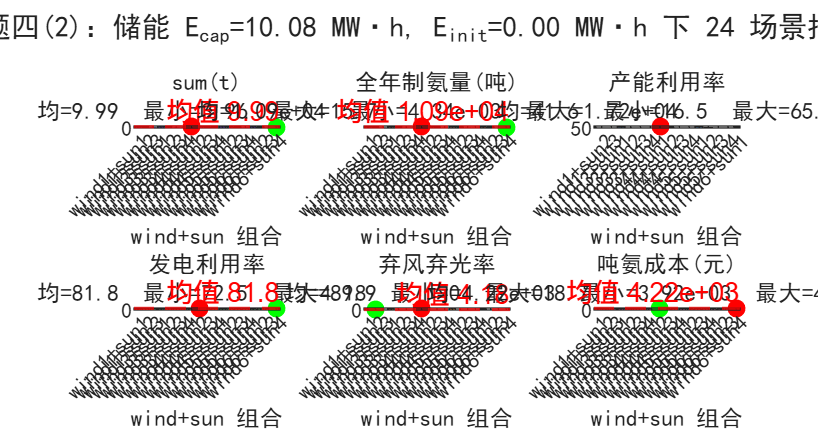


% =========================================================================
% 第四步：绘图
% =========================================================================
plot_p42_metrics(storage_results, E_cap, E_init);

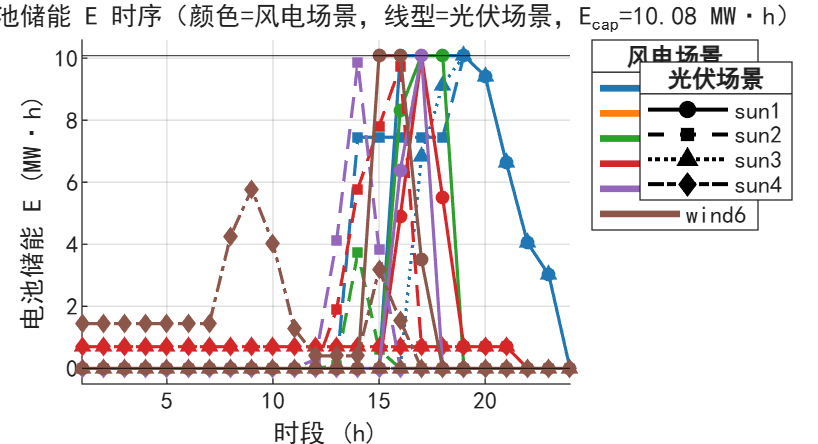

plot_p42_soc_overview(storage_results, E_cap, n);

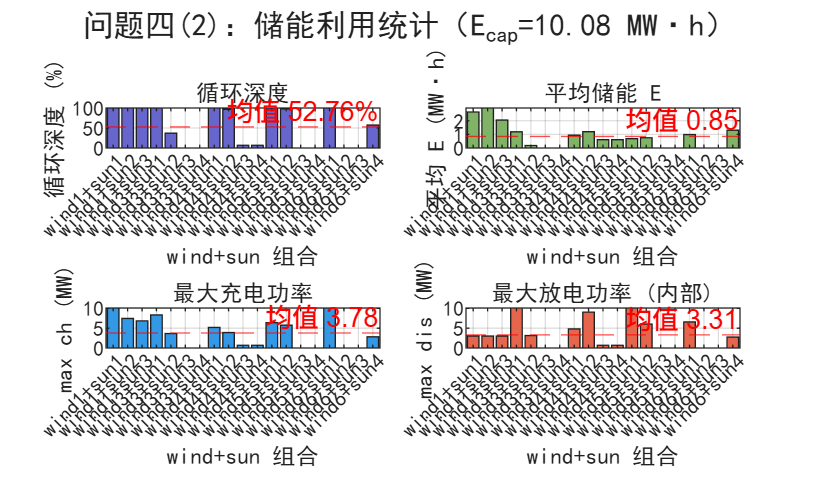

plot_p42_storage_stats(storage_results, E_cap);


% =========================================================================
% 局部函数
% =========================================================================
function plot_p42_metrics(R, E_cap, E_init)
    if isempty(R), warning('无可绘制结果'); return; end
    sort_keys = [[R.wind_idx]', [R.sun_idx]'];
    [~, ord] = sortrows(sort_keys, [1 2]);
    R = R(ord);
    labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), R, 'UniformOutput', false);

    metric_fields = {'sum_t', 'annual_nh3', 'cap_utilization', 'power_util', 'curt_rate', 'J'};
    metric_names  = {'sum(t)', '全年制氨量(吨)', '产能利用率', '发电利用率', '弃风弃光率', '吨氨成本(元)'};
    scale_pct     = [false, false, true, true, true, false];
    colors        = {[0.4 0.2 0.7], [0.85 0.4 0.3], [0.3 0.6 0.85], ...
                     [0.4 0.7 0.4], [0.9 0.5 0.2], [0.7 0.3 0.5]};

    figure('Name', 'problem4-2：24 场景核心指标分布', 'Color', 'w', ...
           'Position', [100 60 1300 700]);
    for mi = 1:numel(metric_fields)
        vals = arrayfun(@(r) r.(metric_fields{mi}), R);
        if scale_pct(mi), vals = vals*100; end
        valid = vals(~isnan(vals));

        subplot(2, 3, mi);
        bar(vals, 'FaceColor', colors{mi}); grid on; hold on;
        yline(mean(valid), 'r--', sprintf('均值 %.3g', mean(valid)), 'LineWidth', 1.2);
        [~,imn] = min(vals); [~,imx] = max(vals);
        scatter(imn, min(valid), 45, 'g', 'filled');
        scatter(imx, max(valid), 45, 'r', 'filled');
        title(sprintf('%s\n均=%.3g  最小=%.3g  最大=%.3g', metric_names{mi}, ...
              mean(valid), min(valid), max(valid)));
        xlabel('wind+sun 组合'); ylabel(metric_names{mi});
        set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
        xlim([0.5, numel(labels)+0.5]);
    end
    sgtitle(sprintf('问题四(2)：储能 E_{cap}=%.2f MW·h, E_{init}=%.2f MW·h 下 24 场景指标', E_cap, E_init));
end

function plot_p42_soc_overview(R, E_cap, n)
    if isempty(R), return; end
    sort_keys = [[R.wind_idx]', [R.sun_idx]'];
    [~, ord] = sortrows(sort_keys, [1 2]);
    R = R(ord);
    t_h = 1:n;

    wind_colors = [0.122 0.467 0.706; 1.000 0.498 0.055; 0.173 0.627 0.173;
                   0.839 0.153 0.157; 0.580 0.404 0.741; 0.549 0.337 0.294];
    sun_styles  = {'-', '--', ':', '-.'};
    sun_markers = {'o', 's', '^', 'd'};

    figure('Name', 'problem4-2：24 场景电池储能 E 曲线', 'Color', 'w', ...
           'Position', [50 50 1200 650]);
    hold on; grid on;
    for k = 1:numel(R)
        r = R(k);
        plot(t_h, r.E_opt, 'Color', wind_colors(r.wind_idx,:), ...
             'LineStyle', sun_styles{r.sun_idx}, 'Marker', sun_markers{r.sun_idx}, ...
             'MarkerSize', 4, 'MarkerFaceColor', wind_colors(r.wind_idx,:), 'LineWidth', 1.2);
    end
    xlabel('时段 (h)'); ylabel('电池储能 E (MW·h)');
    title(sprintf('24 场景下电池储能 E 时序（颜色=风电场景，线型=光伏场景，E_{cap}=%.2f MW·h）', E_cap));
    xlim([1, n]); ylim([-E_cap*0.05, E_cap*1.05]);
    yline(0, 'k-', 'LineWidth', 0.5);
    yline(E_cap, 'k-', 'LineWidth', 0.5);

    % 双图例
    h_w = gobjects(6,1);
    for wi = 1:6, h_w(wi) = plot(NaN, NaN, '-', 'Color', wind_colors(wi,:), 'LineWidth', 2.5); end
    h_s = gobjects(4,1);
    for si = 1:4
        h_s(si) = plot(NaN, NaN, 'Color', 'k', 'LineStyle', sun_styles{si}, ...
                       'Marker', sun_markers{si}, 'MarkerSize', 5, 'MarkerFaceColor', 'k', 'LineWidth', 1.5);
    end
    lg1 = legend(h_w, {'wind1','wind2','wind3','wind4','wind5','wind6'}, ...
                 'Location', 'northeastoutside', 'FontSize', 9);
    title(lg1, '风电场景');
    ax2 = axes('Position', get(gca,'Position'), 'Visible', 'off');
    lg2 = legend(ax2, h_s, {'sun1','sun2','sun3','sun4'}, ...
                 'Location', 'east', 'FontSize', 9);
    title(lg2, '光伏场景');
    lg2.Position(1) = lg1.Position(1);
    lg2.Position(2) = lg1.Position(2) - lg2.Position(4) - 0.02;
end

function plot_p42_storage_stats(R, E_cap)
    if isempty(R), return; end
    sort_keys = [[R.wind_idx]', [R.sun_idx]'];
    [~, ord] = sortrows(sort_keys, [1 2]);
    R = R(ord);
    labels = arrayfun(@(r) sprintf('%s+%s', r.wind_name, r.sun_name), R, 'UniformOutput', false);

    cyc = [R.cycle_depth] * 100;
    mE  = [R.mean_E];
    mch = [R.max_ch];
    mdi = [R.max_dis];

    figure('Name', 'problem4-2：储能利用统计', 'Color', 'w', 'Position', [120 120 1200 700]);
    subplot(2,2,1);
    bar(cyc, 'FaceColor', [0.4 0.4 0.8]); grid on; hold on;
    yline(mean(cyc), 'r--', sprintf('均值 %.2f%%', mean(cyc)));
    title('循环深度'); xlabel('wind+sun 组合'); ylabel('循环深度 (%)');
    set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
    xlim([0.5, numel(labels)+0.5]);

    subplot(2,2,2);
    bar(mE, 'FaceColor', [0.5 0.7 0.4]); grid on; hold on;
    yline(mean(mE), 'r--', sprintf('均值 %.2f', mean(mE)));
    title('平均储能 E'); xlabel('wind+sun 组合'); ylabel('平均 E (MW·h)');
    set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
    xlim([0.5, numel(labels)+0.5]);

    subplot(2,2,3);
    bar(mch, 'FaceColor', [0.2 0.6 0.9]); grid on; hold on;
    yline(mean(mch), 'r--', sprintf('均值 %.2f', mean(mch)));
    title('最大充电功率'); xlabel('wind+sun 组合'); ylabel('max ch (MW)');
    set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
    xlim([0.5, numel(labels)+0.5]);

    subplot(2,2,4);
    bar(mdi, 'FaceColor', [0.9 0.4 0.3]); grid on; hold on;
    yline(mean(mdi), 'r--', sprintf('均值 %.2f', mean(mdi)));
    title('最大放电功率 (内部)'); xlabel('wind+sun 组合'); ylabel('max dis (MW)');
    set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
    xlim([0.5, numel(labels)+0.5]);

    sgtitle(sprintf('问题四(2)：储能利用统计（E_{cap}=%.2f MW·h）', E_cap));
end

%% ============================================================
%  问题四(2) 补充：储能运维费 + 储能带来的自给与利用改善分析
%  前提：工作区已存在 storage_results, p41_extra, E_cap
%  ============================================================
fprintf('\n==================== 问题四(2) 补充：储能成本与改善分析 ====================\n');


==================== 问题四(2) 补充：储能成本与改善分析 ====================


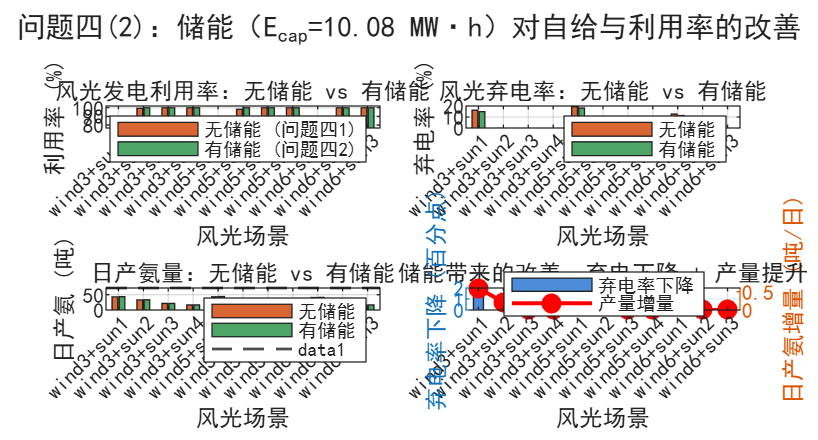


% ---------- 补算储能运维费（附件6: 0.01 元/kWh，按吞吐量） ----------
om_storage_rate = 0.01;       % 元/kWh
P_w = 40; P_s = 64;

for k = 1:numel(storage_results)
    r = storage_results(k);
    % 吞吐量 = 充电+放电（按内部计）
    throughput_day = sum(r.ch_opt) + sum(r.dis_opt);   % MW·h/天
    cost_om_storage = throughput_day * 1000 * om_storage_rate;   % 元/天
    
    % 重新核算吨氨成本（在原 J 基础上加运维费）
    sum_t = r.sum_t;
    cost_om     = 0.75*2*sum_t*2 + 10*2*sum_t*100 + 10*2*sum_t*150;
    cost_nh3_cap= 1.5*2*1000*0.2*60000/365/30;
    wind = wind_vectors{r.wind_idx};
    sun  = sun_vectors{r.sun_idx};
    cost_pv     = sum(sun)*P_s*1000*0.12;
    cost_wind   = sum(wind)*P_w*1000*0.15;
    cost_storage_inv = E_cap * 1000 * 1000 / 365 / 15;
    cost_total_new   = cost_om + cost_nh3_cap + cost_pv + cost_wind + ...
                       cost_storage_inv + cost_om_storage;
    J_new            = cost_total_new / (sum_t * 3);
    
    storage_results(k).throughput_day  = throughput_day;
    storage_results(k).cost_om_storage = cost_om_storage;
    storage_results(k).cost_storage_inv= cost_storage_inv;
    storage_results(k).cost_total      = cost_total_new;
    storage_results(k).J_full          = J_new;          % 含储能运维的完整吨氨成本
end

% ---------- 对比"无储能 problem4_1" vs "有储能 problem4_2" ----------
% 注意：problem4_1 与 problem4_2 都是 24 场景，但 problem4_1 全部 24 场景成功
%       problem4_2 可能有 failed_cases（缺电不可行）；只对都成功的场景做对比

% 索引对齐：用 (wind_idx, sun_idx) 做 key
key_p41 = arrayfun(@(r) (r.wind_idx-1)*4 + r.sun_idx, p41_extra);
key_p42 = arrayfun(@(r) (r.wind_idx-1)*4 + r.sun_idx, storage_results);

common_keys = intersect(key_p41, key_p42);
n_common = numel(common_keys);

cmp_table = zeros(n_common, 8);   % 列：自给率p41/p42, 利用率p41/p42, 弃电率p41/p42, 产量p41/p42
cmp_labels = cell(n_common, 1);

for i = 1:n_common
    key = common_keys(i);
    i_p41 = find(key_p41 == key, 1);
    i_p42 = find(key_p42 == key, 1);
    
    r41 = p41_extra(i_p41);
    r42 = storage_results(i_p42);
    
    % 离网带储能后："自给率"恒为100%（不许买卖电），所以核心是看
    %   1) 产量提升（sum_t 越大越好）
    %   2) 弃电率下降
    %   3) 风光利用率提升
    
    cmp_table(i,1) = 100;                          % p41 自给率（理论上是 100，因为离网不允许缺电）
    cmp_table(i,2) = 100;                          % p42 同
    cmp_table(i,3) = r41.power_use * 100;          % p41 风光利用率
    cmp_table(i,4) = (1 - r42.curt_rate) * 100;    % p42 风光利用率
    cmp_table(i,5) = r41.curt_rate * 100;
    cmp_table(i,6) = r42.curt_rate * 100;
    % 取问题四(1) 对应场景的 sum_t
    p41_sum_t = sum(problem4_results(arrayfun(@(r) (r.wind_idx-1)*4+r.sun_idx, ...
                                              problem4_results) == key).t_opt);
    cmp_table(i,7) = p41_sum_t * 3;                % p41 日产氨 (吨)
    cmp_table(i,8) = r42.sum_t * 3;                % p42 日产氨 (吨)
    cmp_labels{i} = sprintf('%s+%s', r41.wind_name, r41.sun_name);
end

% ---------- 绘改善对比图 ----------
figure('Name', '问题四(2)：储能带来的改善', 'Color', 'w', 'Position', [80 80 1300 700]);

subplot(2,2,1);
bar_data = cmp_table(:,[3 4]);
b_h = bar(bar_data, 'grouped'); grid on;
b_h(1).FaceColor = [0.85 0.40 0.20];
b_h(2).FaceColor = [0.30 0.65 0.40];
title('风光发电利用率：无储能 vs 有储能');
ylabel('利用率 (%)'); xlabel('风光场景');
legend({'无储能 (问题四1)', '有储能 (问题四2)'}, 'Location', 'southeast');
set(gca, 'XTick', 1:n_common, 'XTickLabel', cmp_labels, 'XTickLabelRotation', 45);
xlim([0.5, n_common+0.5]); ylim([min(bar_data(:))*0.95, 102]);

subplot(2,2,2);
bar_data = cmp_table(:,[5 6]);
b_h = bar(bar_data, 'grouped'); grid on;
b_h(1).FaceColor = [0.85 0.40 0.20];
b_h(2).FaceColor = [0.30 0.65 0.40];
title('风光弃电率：无储能 vs 有储能');
ylabel('弃电率 (%)'); xlabel('风光场景');
legend({'无储能', '有储能'}, 'Location', 'northeast');
set(gca, 'XTick', 1:n_common, 'XTickLabel', cmp_labels, 'XTickLabelRotation', 45);
xlim([0.5, n_common+0.5]);

subplot(2,2,3);
bar_data = cmp_table(:,[7 8]);
b_h = bar(bar_data, 'grouped'); grid on;
b_h(1).FaceColor = [0.85 0.40 0.20];
b_h(2).FaceColor = [0.30 0.65 0.40];
title('日产氨量：无储能 vs 有储能');
ylabel('日产氨 (吨)'); xlabel('风光场景');
legend({'无储能', '有储能'}, 'Location', 'southeast');
set(gca, 'XTick', 1:n_common, 'XTickLabel', cmp_labels, 'XTickLabelRotation', 45);
xlim([0.5, n_common+0.5]); yline(72, 'k--', '设计产能 72 t/d', 'LineWidth', 1.0);

subplot(2,2,4);
% 弃电率下降幅度
drop_curt = cmp_table(:,5) - cmp_table(:,6);
% 产量提升幅度
gain_yield = cmp_table(:,8) - cmp_table(:,7);
yyaxis left;
bar(1:n_common, drop_curt, 0.4, 'FaceColor', [0.30 0.55 0.85]);
ylabel('弃电率下降 (百分点)');
yyaxis right;
plot(1:n_common, gain_yield, 'ro-', 'LineWidth', 1.5, 'MarkerFaceColor', 'r');
ylabel('日产氨增量 (吨/日)');
xlabel('风光场景');
title('储能带来的改善：弃电下降 + 产量提升');
grid on;
set(gca, 'XTick', 1:n_common, 'XTickLabel', cmp_labels, 'XTickLabelRotation', 45);
xlim([0.5, n_common+0.5]);
legend({'弃电率下降', '产量增量'}, 'Location', 'best');

sgtitle(sprintf('问题四(2)：储能（E_{cap}=%.2f MW·h）对自给与利用率的改善', E_cap));
saveas(gcf, 'problem4_2_improvement.png');


% ---------- 控制台结论 ----------
fprintf('\n--- 储能带来的改善（按 %d 个共同场景核算）---\n', n_common);


--- 储能带来的改善（按 11 个共同场景核算）---


fprintf('1) 风光利用率：无储能 %.2f%% → 有储能 %.2f%%（提升 %.2f 百分点）\n', ...
        mean(cmp_table(:,3)), mean(cmp_table(:,4)), mean(cmp_table(:,4)-cmp_table(:,3)));

1) 风光利用率：无储能 95.39% → 有储能 95.97%（提升 0.58 百分点）


fprintf('2) 弃电率：无储能 %.2f%% → 有储能 %.2f%%（下降 %.2f 百分点）\n', ...
        mean(cmp_table(:,5)), mean(cmp_table(:,6)), mean(cmp_table(:,5)-cmp_table(:,6)));

2) 弃电率：无储能 4.61% → 有储能 4.03%（下降 0.58 百分点）


fprintf('3) 日产氨量：无储能 %.2f t/d → 有储能 %.2f t/d（增量 %.2f t/d）\n', ...
        mean(cmp_table(:,7)), mean(cmp_table(:,8)), mean(cmp_table(:,8)-cmp_table(:,7)));

3) 日产氨量：无储能 29.34 t/d → 有储能 29.57 t/d（增量 0.23 t/d）


fprintf('4) 储能投资日摊 = %.2f 元/天，平均储能运维费 = %.2f 元/天\n', ...
        E_cap * 1000 * 1000 / 365 / 15, mean([storage_results.cost_om_storage]));

4) 储能投资日摊 = 1841.03 元/天，平均储能运维费 = 109.28 元/天


fprintf('5) 含储能运维后的平均吨氨成本 J_full = %.2f 元/吨\n', mean([storage_results.J_full]));

5) 含储能运维后的平均吨氨成本 J_full = 4226.14 元/吨


fprintf('   （旧 J 未含运维 = %.2f 元/吨，差 %.2f 元/吨）\n', ...
        mean([storage_results.J]), mean([storage_results.J_full]) - mean([storage_results.J]));

   （旧 J 未含运维 = 4222.57 元/吨，差 3.56 元/吨）


%% ============================================================
%  问题四(3)：离网（带储能）vs 联网 经济性对比
%  前提：
%    - problem3_results: 联网，连续可调，包含 beq=24 的 24 场景结果
%    - storage_results : 离网带储能，每个场景 sum_t 可能不同
%  对比口径：相同产量需求（题目要求"满足相同制氨产量"）
%  ============================================================
fprintf('\n==================== 问题四(3)：离网 vs 联网 经济性对比 ====================\n');


==================== 问题四(3)：离网 vs 联网 经济性对比 ====================


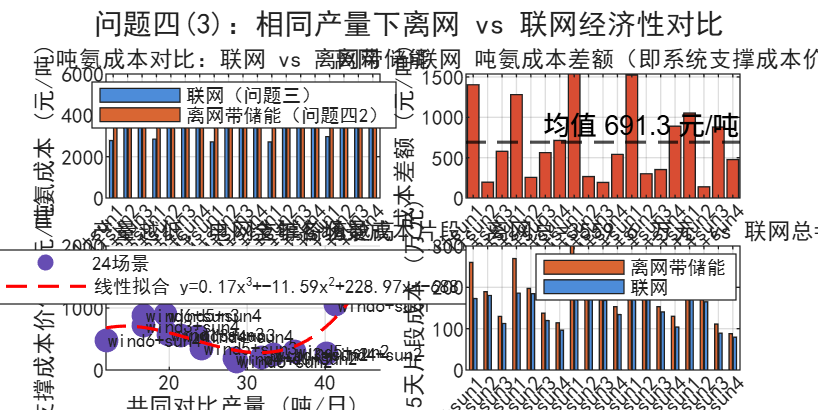


% ---------- 提取联网结果（beq=24, 即 72 t/d 设计产能） ----------
% problem3_results 里每个场景有 5 个 beq，对比时要拿哪一个？
% 题目说"满足相同制氨产量"。离网带储能下，每个场景产量不同（≤72 t/d）。
% 严格对比口径：对每个场景，找到 problem3_results 里产量"最接近"离网产量的 beq
% 但 beq 离散（24/21/18/15/12 → 72/63/54/45/36 t/d），所以做线性插值

p3_grid = cell(24, 5);
for k = 1:numel(problem3_results)
    r = problem3_results(k);
    scen = (r.wind_idx - 1)*4 + r.sun_idx;
    bcol = find([24 21 18 15 12] == r.beq);
    p3_grid{scen, bcol} = r;
end

cmp_econ = struct([]);
for k = 1:numel(storage_results)
    r42 = storage_results(k);
    scen = (r42.wind_idx - 1)*4 + r42.sun_idx;
    
    daily_yield_42 = r42.sum_t * 3;   % 离网日产氨 (吨)
    
    % 在联网 5 个 beq 中按产量线性插值吨氨成本
    p3_yields = [72 63 54 45 36];
    p3_J = zeros(1, 5);
    for b = 1:5
        if ~isempty(p3_grid{scen, b})
            p3_J(b) = p3_grid{scen, b}.J_min;
        else
            p3_J(b) = NaN;
        end
    end
    valid = ~isnan(p3_J);
    if sum(valid) >= 2
        % 联网相同产量下的吨氨成本（线性插值/外推）
        J_grid_at_yield = interp1(p3_yields(valid), p3_J(valid), daily_yield_42, ...
                                  'linear', 'extrap');
    else
        J_grid_at_yield = NaN;
    end
    
    cmp_econ(k).case_idx    = k;
    cmp_econ(k).label       = sprintf('%s+%s', r42.wind_name, r42.sun_name);
    cmp_econ(k).wind_idx    = r42.wind_idx;
    cmp_econ(k).sun_idx     = r42.sun_idx;
    cmp_econ(k).yield       = daily_yield_42;          % 共同对比产量 (t/d)
    cmp_econ(k).J_offgrid   = r42.J_full;              % 离网含运维
    cmp_econ(k).J_ongrid    = J_grid_at_yield;         % 联网同产量
    cmp_econ(k).J_diff      = r42.J_full - J_grid_at_yield;  % 离网比联网贵多少
    cmp_econ(k).support_val = r42.J_full - J_grid_at_yield;  % 系统支撑成本价值（同义）
end

% ---------- 排序后绘图 ----------
sort_keys = [[cmp_econ.wind_idx]', [cmp_econ.sun_idx]'];
[~, ord] = sortrows(sort_keys, [1 2]);
cmp_econ = cmp_econ(ord);
labels = {cmp_econ.label};

J_off = [cmp_econ.J_offgrid];
J_on  = [cmp_econ.J_ongrid];
J_dif = [cmp_econ.J_diff];
yields = [cmp_econ.yield];

figure('Name', '问题四(3)：离网 vs 联网经济性', 'Color', 'w', 'Position', [80 80 1400 700]);

% (a) 吨氨成本双柱对比
subplot(2,2,1);
bar_data = [J_on; J_off]';
b_h = bar(bar_data, 'grouped'); grid on; hold on;
b_h(1).FaceColor = [0.30 0.55 0.85];
b_h(2).FaceColor = [0.85 0.40 0.20];
title('吨氨成本对比：联网 vs 离网带储能');
xlabel('风光场景'); ylabel('吨氨成本 (元/吨)');
legend({'联网（问题三）', '离网带储能（问题四2）'}, 'Location', 'best');
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
xlim([0.5, numel(labels)+0.5]);

% (b) 成本差额 = 系统支撑成本价值
subplot(2,2,2);
colors_diff = J_dif;
b_h = bar(J_dif); grid on; hold on;
% 正值（离网更贵）红，负值（离网更便宜）绿
b_h.FaceColor = 'flat';
for k = 1:numel(J_dif)
    if J_dif(k) > 0
        b_h.CData(k,:) = [0.85 0.30 0.20];
    else
        b_h.CData(k,:) = [0.30 0.65 0.40];
    end
end
yline(mean(J_dif), 'k--', sprintf('均值 %.1f 元/吨', mean(J_dif)), 'LineWidth', 1.2);
title('离网 - 联网 吨氨成本差额（即系统支撑成本价值）');
xlabel('风光场景'); ylabel('成本差额 (元/吨)');
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
xlim([0.5, numel(labels)+0.5]);

% (c) 散点：产量 vs 成本差
subplot(2,2,3);
scatter(yields, J_dif, 80, [0.40 0.30 0.70], 'filled'); grid on; hold on;
for k = 1:numel(labels)
    text(yields(k)+0.3, J_dif(k), labels{k}, 'FontSize', 7);
end
xlabel('共同对比产量 (吨/日)'); ylabel('支撑成本价值 (元/吨)');
title('产量越低，电网支撑价值越高');
p_fit = polyfit(yields, J_dif, 3);
xx = linspace(min(yields), max(yields), 50);
plot(xx, polyval(p_fit, xx), 'r--', 'LineWidth', 1.2);
legend({'24场景', sprintf('线性拟合 y=%.2fx^3+%.2fx^2+%.2fx+%.0f', p_fit(1), p_fit(2),p_fit(3),p_fit(4))}, ...
       'Location', 'best');

% (d) 全年总成本对比（按每场景代表 15 天）
subplot(2,2,4);
DAYS_PER = 15;
annual_cost_off = J_off .* yields * DAYS_PER;   % 元/场景的全年片段
annual_cost_on  = J_on  .* yields * DAYS_PER;
annual_yield    = yields * DAYS_PER;

total_off = sum(annual_cost_off);
total_on  = sum(annual_cost_on);
total_y   = sum(annual_yield);
mean_off  = total_off / total_y;
mean_on   = total_on  / total_y;

stem_data = [annual_cost_off; annual_cost_on]' / 1e4;   % 万元
b_h = bar(stem_data, 'grouped'); grid on; hold on;
b_h(1).FaceColor = [0.85 0.40 0.20];
b_h(2).FaceColor = [0.30 0.55 0.85];
title(sprintf('全年各场景成本片段：离网总=%.1f 万元 vs 联网总=%.1f 万元', ...
              total_off/1e4, total_on/1e4));
xlabel('风光场景'); ylabel('15天片段成本 (万元)');
legend({'离网带储能', '联网'}, 'Location', 'best');
set(gca, 'XTick', 1:numel(labels), 'XTickLabel', labels, 'XTickLabelRotation', 45);
xlim([0.5, numel(labels)+0.5]);

sgtitle('问题四(3)：相同产量下离网 vs 联网经济性对比');
saveas(gcf, 'problem4_3_economic_compare.png');


% ---------- 控制台结论 ----------
fprintf('\n--- 经济性对比关键结论 ---\n');


--- 经济性对比关键结论 ---


fprintf('1) 24 场景平均吨氨成本：\n');

1) 24 场景平均吨氨成本：


fprintf('   - 联网（问题三同产量插值）: %.2f 元/吨\n', mean(J_on));

   - 联网（问题三同产量插值）: 3534.79 元/吨


fprintf('   - 离网带储能（问题四2）  : %.2f 元/吨\n', mean(J_off));

   - 离网带储能（问题四2）  : 4226.14 元/吨


fprintf('   - 平均差额（离网-联网）  : %.2f 元/吨\n', mean(J_dif));

   - 平均差额（离网-联网）  : 691.34 元/吨


fprintf('\n2) 全年加权平均吨氨成本（按每场景 15 天权重）：\n');


2) 全年加权平均吨氨成本（按每场景 15 天权重）：


fprintf('   - 联网    : %.2f 元/吨\n', mean_on);

   - 联网    : 3399.73 元/吨


fprintf('   - 离网带储能: %.2f 元/吨\n', mean_off);

   - 离网带储能: 4166.61 元/吨


fprintf('   - 全年支撑成本价值: %.2f 元/吨\n', mean_off - mean_on);

   - 全年支撑成本价值: 766.87 元/吨


fprintf('\n3) 全年总成本（按 15 天 × 24 场景 = 360 天，但产量不一致）：\n');


3) 全年总成本（按 15 天 × 24 场景 = 360 天，但产量不一致）：


fprintf('   - 联网全年总成本     : %.2e 元\n', total_on);

   - 联网全年总成本     : 2.90e+07 元


fprintf('   - 离网带储能全年总成本: %.2e 元\n', total_off);

   - 离网带储能全年总成本: 3.56e+07 元


fprintf('   - 全年成本差（电网支撑总价值）: %.2e 元\n', total_off - total_on);

   - 全年成本差（电网支撑总价值）: 6.55e+06 元


fprintf('\n4) 极端场景：\n');


4) 极端场景：


[~, max_idx] = max(J_dif);
[~, min_idx] = min(J_dif);
fprintf('   - 最依赖电网场景: %s（离网比联网贵 %.2f 元/吨）\n', ...
        labels{max_idx}, J_dif(max_idx));

   - 最依赖电网场景: wind4+sun1（离网比联网贵 1536.52 元/吨）


fprintf('   - 最不依赖电网场景: %s（差额仅 %.2f 元/吨）\n', ...
        labels{min_idx}, J_dif(min_idx));

   - 最不依赖电网场景: wind6+sun2（差额仅 138.53 元/吨）


fprintf('\n5) 经济结论：\n');


5) 经济结论：


if mean(J_dif) > 0
    fprintf('   - 联网经济性整体优于离网，公共电网提供了 %.2f 元/吨 的系统支撑价值\n', ...
            mean(J_dif));
    fprintf('   - 该价值主要来源于：①电网平抑风光波动，避免储能投资；\n');
    fprintf('     ②谷电低价补充电源；③消纳余电创造上网收益\n');
end

   - 联网经济性整体优于离网，公共电网提供了 691.34 元/吨 的系统支撑价值


   - 该价值主要来源于：①电网平抑风光波动，避免储能投资；


     ②谷电低价补充电源；③消纳余电创造上网收益



% ---------- 导出汇总到 Excel ----------
try
    T = table({cmp_econ.label}', [cmp_econ.yield]', [cmp_econ.J_ongrid]', ...
              [cmp_econ.J_offgrid]', [cmp_econ.J_diff]', ...
              'VariableNames', {'场景', '日产氨_吨', '联网吨氨成本', '离网吨氨成本', '支撑价值'});
    writetable(T, 'problem4_3_summary.xlsx');
    fprintf('\n汇总数据已导出：problem4_3_summary.xlsx\n');
catch ME
    warning('Excel 导出失败：%s', ME.message);
end


汇总数据已导出：problem4_3_summary.xlsx
